# Creation des cartes du modèle SDM RQ

clear; clc;
tic

## Definition des variables contextuelles

pc = 'E:/'; % 'C:/Users/lehuen201/Nextcloud/'; % 'Z:/'; %
tsk = 'A_SDM_NEO/';
wdpath = [pc 'Melting Pot/BDD/']; wdwork = [wdpath,tsk,'Matrices/'];
wdres = [wdpath,tsk,'Resultats/'];
wdgraph = [wdpath,tsk,'Graphiques/'];
wdSIG = [pc,'Melting Pot/SIG/Layers made/'];
% wdmaps = ['E:/Copie-HD/' 'Melting Potes/' tsk '/']; % Emplacement de sauvegarde des cartes generees

prgm = 'CSLN';
etude = [prgm,'_Mars'];
etudenc = ['ES','_Mars'];

wb = [wdres,prgm,'_BDD.xlsx'];
coeff_rq = readtable(wb,'Sheet','Rq_coeff'); 

dm_bdd = readtable(wb,'Sheet','CSLN_Mars');
species = readtable(wb,'Sheet','Species');
reponse = readtable(wb,'Sheet','Reponse');
predict = readtable(wb,'Sheet','Predicteurs');

nc2d = load ([wdwork, etudenc, '_Nc2D']);

spe = 1%:nrow(species); % 1:CERED 2:CORVO 3:HEDDI 4:LIMBA 5:PERUL 6:SCRPL

spe = 1

% answ = 2%1:nrow(reponse); # 1:Densite 2: Biomasse
% sai = 1:size(nc2d.saison,1); saison=nc2d.saison;
% sitetxt = 'Seine Estuary'; % bdd.geog{strcmp(bdd.geog(:,1),site),2}; % METTRE DANS LES TITRES DES GRAPHES LE SITE
an = nc2d.an; % [1990:1991 1993:2000 2005:2018]; % 1992 toute plantée enlevée

finesse = 100;
csp = 4; lsp = ceil(size(an,2)/csp);
propplch = [0 0 csp*150+100 lsp*150];  propimg = [0 0 csp*150+100 lsp*150];
palette = 'parula'; %  'jet' 'parula' 'turbo'

# MAPS RESULTAT

make_it_tight = false;
subplot = @(m,n,p) subtightplot (m, n, p, [0.07 0.05], [0.05 0.11], [0.05 0.12]); %[0.01 0.05], [0.1 0.01], [0.1 0.01]
if ~make_it_tight,  clear subplot;  end

### Planche avec tous les ans

for sp = spe % sp = spe; % 
    filename =sprintf('%s%s%s%s',wdSIG,'SDM_NEO_rq_',species.SPCourt{sp},'.shp');
    Mars_SDM = shaperead(filename,'UseGeoCoords',true);
    for sdi = 1 %1:3; %

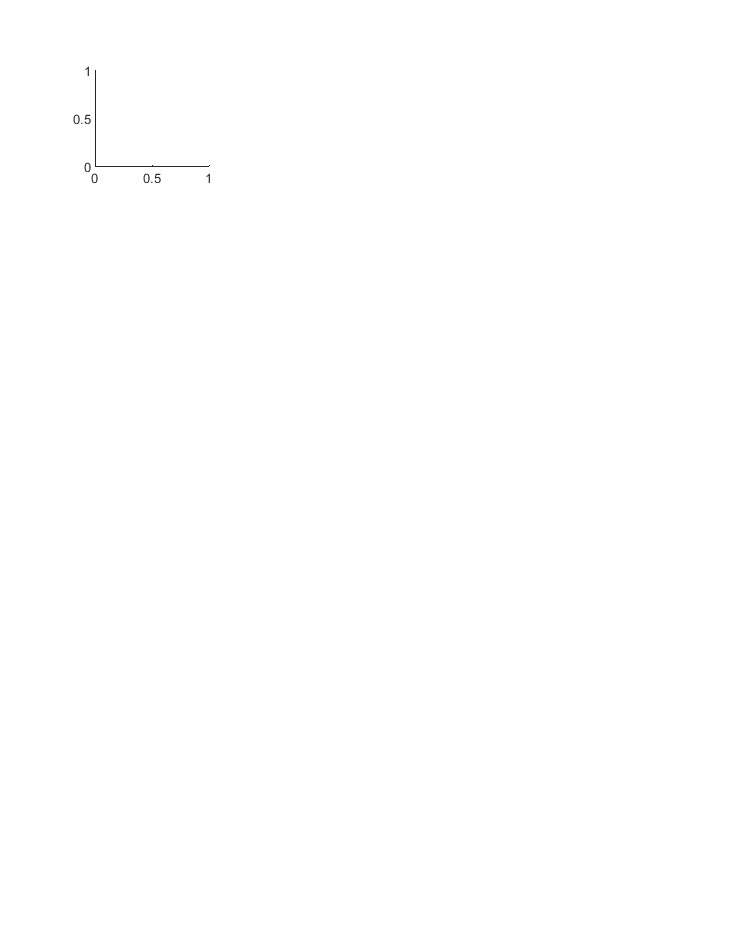

Error using contourf (line 57)
Z must be at least a 2x2 matrix.

        sdmi=[species.SPCourt{sp} 'SDM' num2str(sdi)];
        maxx= eval(['max([Mars_SDM.' sdmi ']);']);
        minn= eval(['min([Mars_SDM.' sdmi ']);']);
        figure;clf;hold on 
        rgvar = [minn maxx]; % [0 100]; % 
        set(gcf, 'Position', propplch);
        for ann = 1%:length(an)
            Mars_SDM_an=Mars_SDM([Mars_SDM.Annee]==an(ann));
            anstr = num2str(an(ann));
            subplot(lsp,csp,ann);hold on
            x = [Mars_SDM_an.Lon_c];
            y = [Mars_SDM_an.Lat_c];
            z = eval(['[Mars_SDM_an.' sdmi '];']);
            mars_dim=eval(['size(nc2d.bathy_' anstr ');']);
            X = reshape(x,mars_dim);
            Y = reshape(y,mars_dim);
            Z = reshape(Z,mars_dim);

            contourf(x,y,z,finesse, 'LineColor','flat')
            caxis(rgvar); colormap(palette); c=colorbar; c.HandleVisibility='off';
            title(anstr);
        end
        hpf = get(subplot(lsp,csp,lsp*csp),'Position');
        caxis(rgvar);
        c.Position = [hpf(1)+hpf(3)+0.01 hpf(2) 0.01 hpf(2)*lsp*0.5+hpf(4)*lsp];
        c.Label.String = yl; c.Label.FontSize = 12;
        titreG = sprintf('%s - %s in %s %s:%s for tau = %s\n%s vs %s', ...
            species{sp,2},sitetxt,saison{sa,2},sdm{sdi,1},sdm{sdi,2},string(tau),yl,strrep(sdm{sdi,8},'_',' '));
        [~,h3] = suplabel(titreG ,'t'); set(h3,'FontSize',10);
        hold off
        saveas(gcf,sprintf('%s%s/RQ Lineaire/%s_%s_%s_Maps_%s%s_%s.png', ...
                    wdgraph,species{sp,1},prgm,site,species{sp,1},sdm{sdi,1},saison{sa,1},yt));

### Une figure par an et GIF associé

        filename = sprintf('%s%s/RQ Lineaire/Map Detail/%s_%s_%s_Map_Anim_%s%s_%s.gif', ...
                    wdgraph,species{sp,1},prgm,site,species{sp,1},sdm{sdi,1},saison{sa,1},yt);
        fig = figure;clf;hold on 
        set(gcf, 'Position', propimg);
        rgvar = [minn maxx]; % [0 100]; % [0 150]; % 
          for ann = 1:length(an)
          hold on
            anstr = num2str(an(ann));
            
            Mars_SDM_an=Mars_SDM([Mars_SDM.Annee]==an(ann));
            subplot(lsp,csp,ann);hold on
            x = [Mars_SDM_an.Lon_c];
            y = [Mars_SDM_an.Lat_c];
            z = eval(['[Mars_SDM_an.' sdmi '];']);
            mars_dim=eval(['size(nc2d.bathy_' anstr ');']);
            X = reshape(x,mars_dim);
            Y = reshape(y,mars_dim);
            Z = reshape(Z,mars_dim);

            contourf(x,y,z,finesse, 'LineColor','flat') % ,'--','LineWidth',.1 ,'ShowText','on'
            colormap(palette); c = colorbar; c.Label.String = yl; c.Label.FontSize = 12;
            scatter(dm_bdd(dm_bdd.Annee == anstr,:).longitude,dm_bdd(dm_bdd.Annee == anstr,:).latitude,20,[0.4 0.4 0.4])
            caxis(rgvar);
            xlabel('Longitude','FontSize',8); ylabel('Latitude','FontSize',8);
            titreG = sprintf('%s - %s in %s %s %s:%s for tau = %s\n%s vs %s', ...
                species{sp,2},sitetxt,saison{sa,2},anstr,sdm{sdi,1},sdm{sdi,2},string(tau),yl,strrep(sdm{sdi,8},'_',' '));
            title(titreG,'FontSize',8,'FontWeight','bold');
            saveas(gcf,sprintf('%s%s/RQ Lineaire/Map Detail/%s_%s_%s_Map_%s%s_%s_%s.png', ...
                    wdgraph,species{sp,1},prgm,site,species{sp,1},sdm{sdi,1},saison{sa,1},yt,anstr));
            % Capture the plot as an image 
            frame = getframe(fig); 
            im = frame2im(frame); 
            [imind,cm] = rgb2ind(im,256); 
            % Write to the GIF File 
            if ann == 1 
                imwrite(imind,cm,filename,'gif', 'Loopcount',inf); 
            else 
                imwrite(imind,cm,filename,'gif','WriteMode','append'); 
            end 
            hold off
          end
    end
end

toc
beep